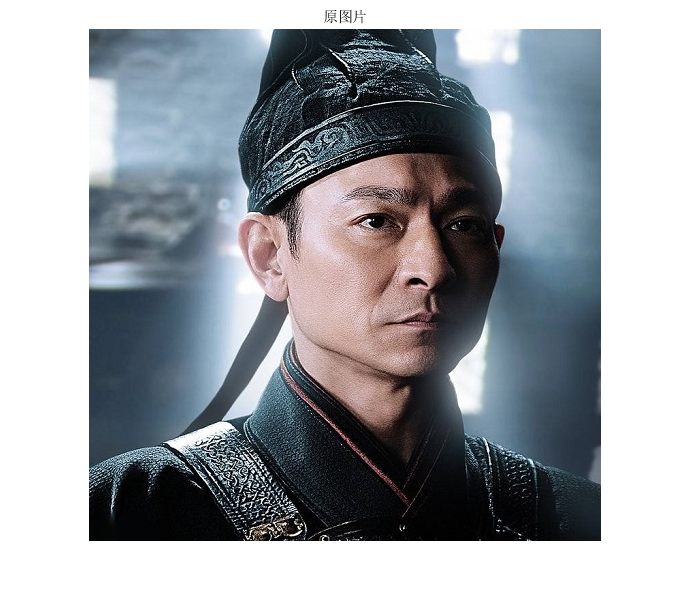

clc;
clear;
I=imread("11-刘德华.jpg");
I=im2double(I);
figure
imshow(I);
title("原图片");

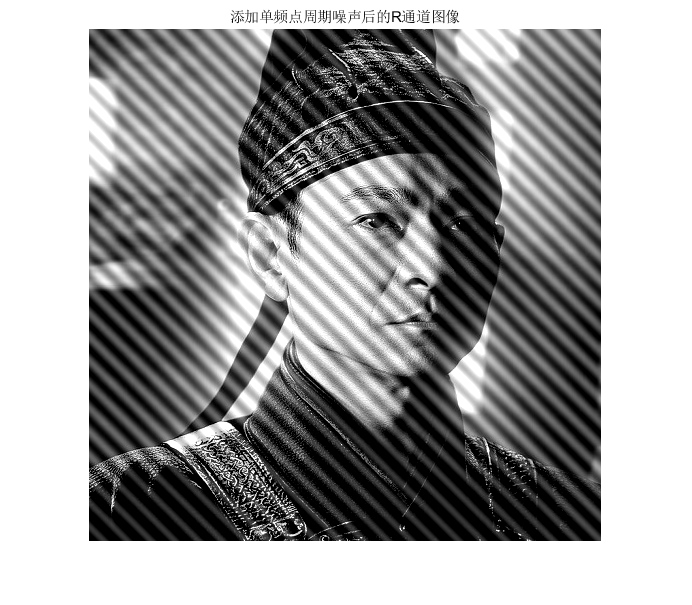

%取出RG通道
I_R=I(:,:,1);
I_G=I(:,:,2);
I_Rn=I_R;
[row,col,~]=size(I);
%对R通道添加单一频点周期噪声
val=0.2; %赋值
w=50; %频率
for i=1:row
    for j=1:col
        I_Rn(i,j)=I_R(i,j)+val*cos(w*(i-j));
    end
end
%绘图
I_Rn=uint8(I_Rn*255);
figure
imshow(I_Rn);
title('添加单频点周期噪声后的R通道图像')

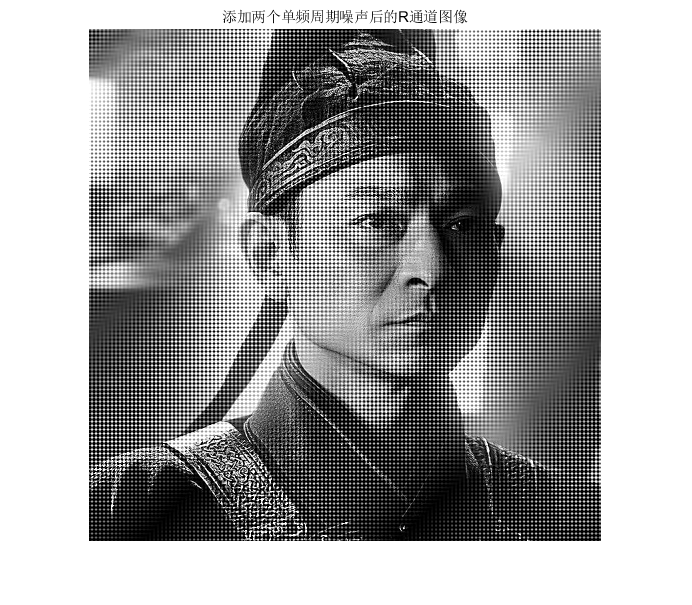

%求G通道的频谱
Y=fftshift(fft2(I_G));
[m,n]=size(Y);
%求中心点
M0=m/2;
N0=n/2;
%求出最大频率和最大峰值幅度的一半
w=m/2/2;
val=max(abs(Y),[],"all")/2;
%添加噪声频点
Y(M0,N0-w)=val*exp(1i*angle(Y(M0,N0-w)));
Y(M0,N0+w)=val*exp(1i*angle(Y(M0,N0+w)));
Y(M0-w,N0)=val*exp(1i*angle(Y(M0-w,N0)));
Y(M0+w,N0)=val*exp(1i*angle(Y(M0+w,N0)));
%反变换
I_Gn=real(ifft2(ifftshift(Y)));
%绘制结果
figure
imshow(I_Gn);
title('添加两个单频周期噪声后的R通道图像')

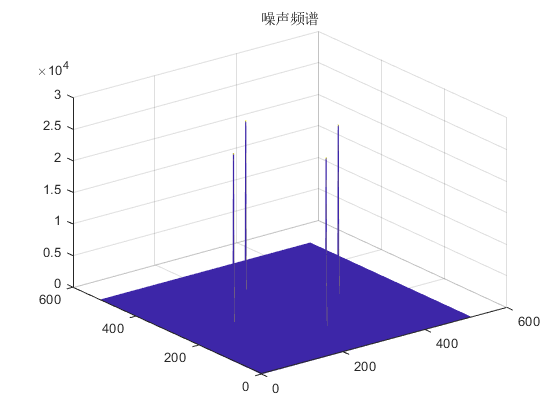

%绘制噪声频谱图
noise=I_Gn-I_G; %求出噪声
fft_n=fftshift(fft2(noise)); %求噪声频谱
u=1:m;
v=1:n;
[U,V]=meshgrid(u,v); %创建绘图网络
fig=figure();
mesh(U,V,abs(fft_n)); %绘制三维噪声频谱
title("噪声频谱");
saveas(fig,'噪声频谱.jpg',"jpg");

%储存
imwrite(I_Rn,'添加单频点周期噪声的R通道图像.jpg',"jpg");
imwrite(I_Gn,'添加两个单频点周期噪声的G通道图像.jpg',"jpg");